## Torque Requirements - Center Aligned

### Equations

syms F1 F2 Fr T D

FV1 = [0 -F1 0];
FV2 = F2*[-sin(theta) cos(theta) 0];
eq1 = approx_mass*g==2*F2*cos(theta);
eq2 = cross(bearing.r1, FV1)+cross(bearing.r2, FV2)-[0 0 (norm(FV1+FV2)*bearing.mu*bearing.PD)/2] ==0;
eq2 = eq2(3);
eq3 = T==F1*D/2;

F2Sol1 = vpa(solve(eq1,F2));
F2Sol=@(t) double(subs(F2Sol1,theta,t));
F1Sol =@(t) double(vpasolve(subs(subs(eq2,F2,F2Sol(t)), theta, t),F1));

theta_vals = linspace(0,pi/2-pi/64,20);
y_F2 = arrayfun(F2Sol, theta_vals);
y_F1 = arrayfun(F1Sol, theta_vals);

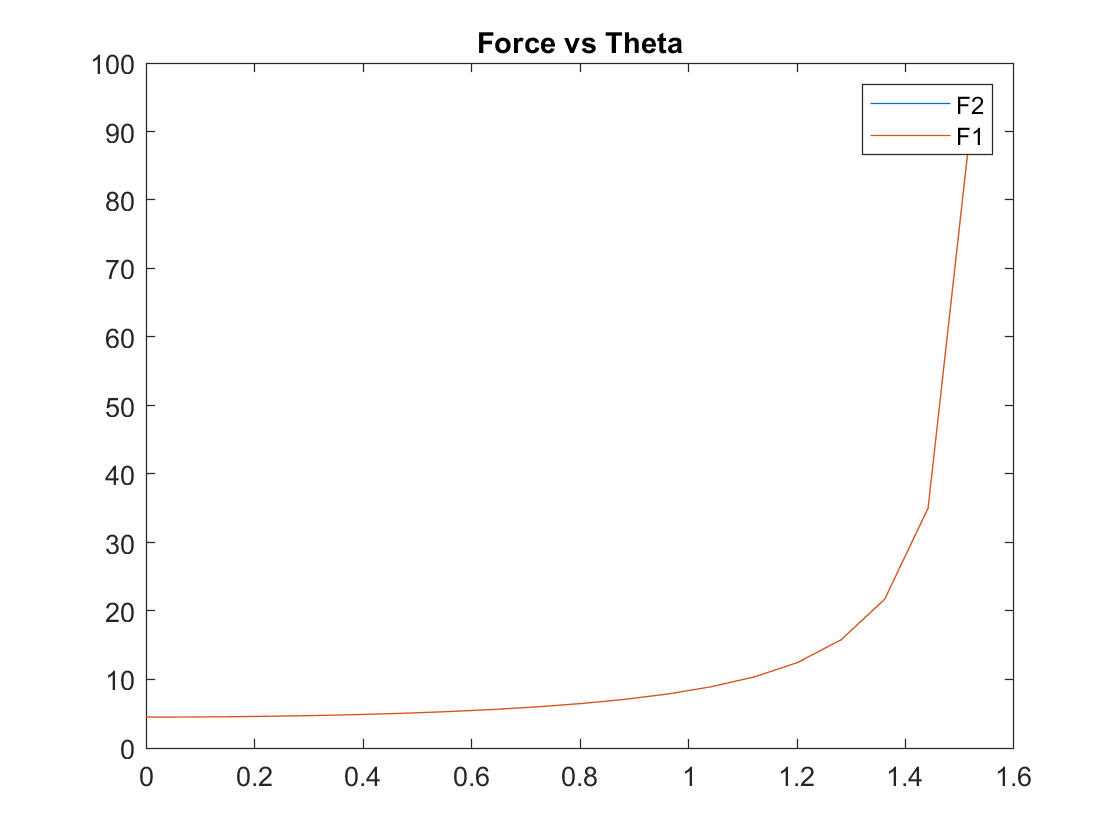

plot(theta_vals, y_F2, theta_vals, y_F1);
legend(["F2", "F1"])
title('Force vs Theta')

Trq = @(D,t) F1Sol(t)*D/2; %N*m
D_vals = linspace(1,10,10)/100; % 1-10 cm, to m
y_Trq = zeros(length(D_vals), length(theta_vals));
for i_t = 1:length(theta_vals)
    for i_d = 1:length(D_vals)
        y_Trq(i_d,i_t) = Trq(D_vals(i_d), theta_vals(i_t));
    end
end

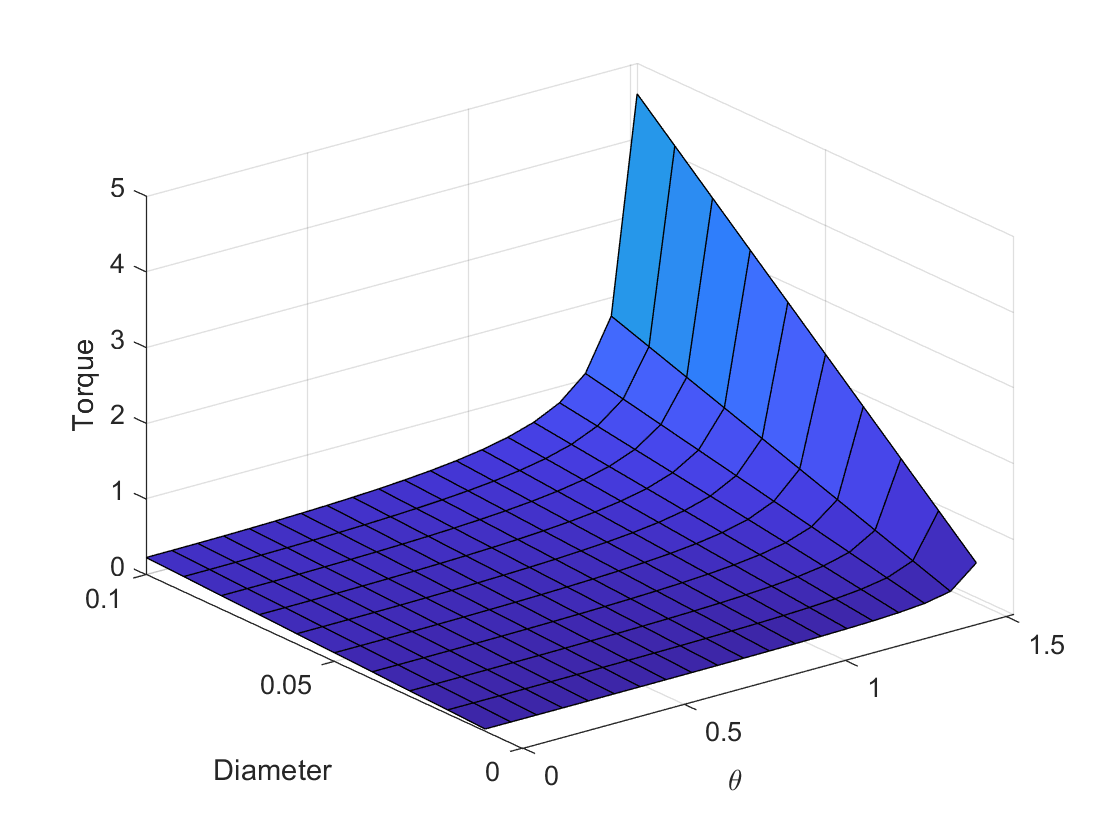

surf(theta_vals,D_vals, y_Trq)
xlabel("\theta")
ylabel("Diameter")
zlabel("Torque")

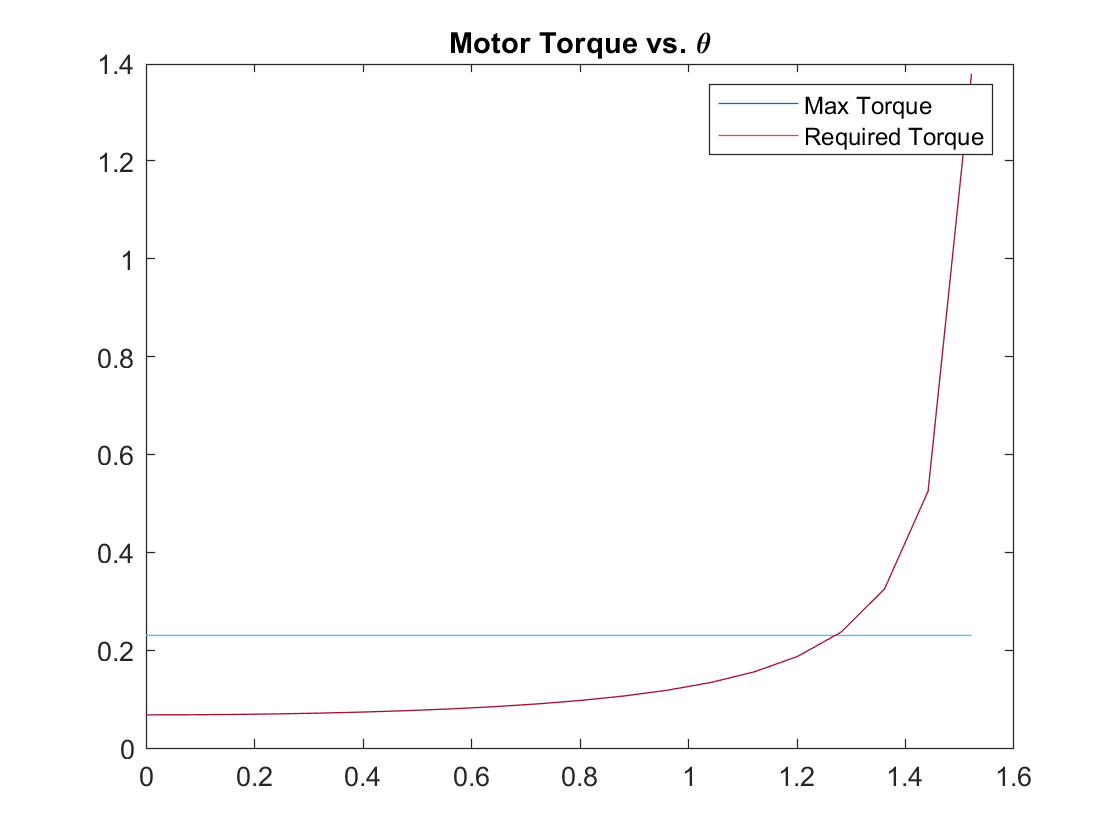

plot(theta_vals, ones(length(theta_vals))*motor.max_holding_torque,theta_vals, arrayfun(@(t) Trq(.03, t), theta_vals))
title("Motor Torque vs. \theta");
legend(["Max Torque", "Required Torque"])

We can do around \theta=60deg max when drawbot is centered.

%Work out 2D version of this